%R=4 and d=10 give some beautiful results 

%First the model is simulated to obtained some 
%Data which can be utilized by the HAVOK 
clear
simTimEnd=100;
samplingTime=0.01;

%Genertaing inital value of state x1 and x2
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x1=a+(b-a)*rand();
x2=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=1; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
    %The contious time model: 
    x1dot=2*x2(index,1);
    x2dot=-0.8*x1(index,1)+2*x2(index,1)-10*x1(index,1)^2*x2(index,1);
    
   %Using forward euler to get the states value: 
    index=index+1; 
    x1(index,1)=x1dot*samplingTime+x1(index-1,1);
    x2(index,1)=x2dot*samplingTime+x2(index-1,1);
end

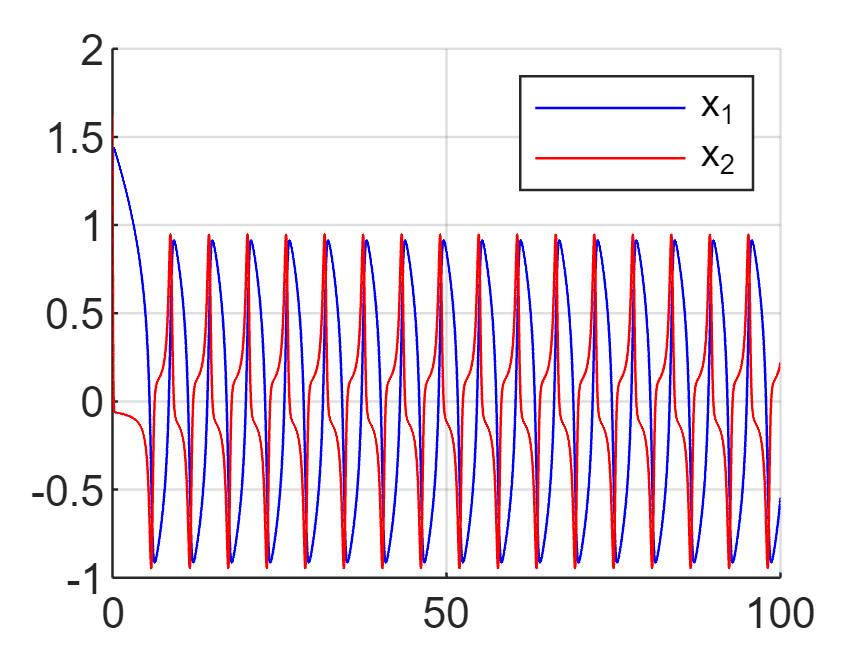

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 

hold on 
plot(time,x1,'blue')
plot(time,x2,'red')
hold off 
grid
legend('x_1','x_2')

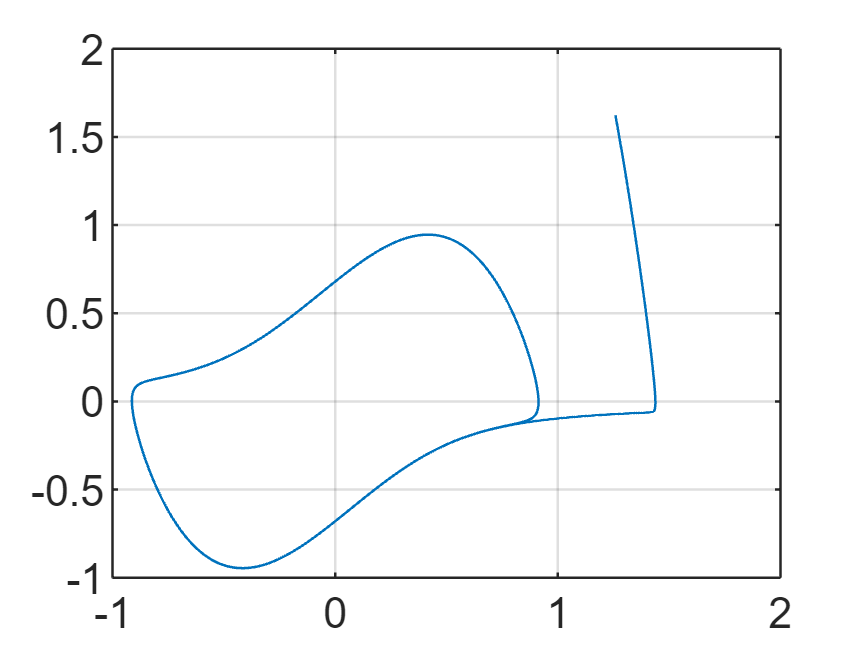



plot(x1,x2)
grid

%Making the Hankel matrix, which will be based on 5000 points, and a delay
%of 50 

d=50; 
index=1;

    for i=0:d 
        H(index,:)=x1(d-i+1:5000-i); 
        index=index+1;
        H(index,:)=x2(d-i+1:5000-i); 
        index=index+1;
    end 


%Takning the SVD of the Hankel matirx 
[U,S,V]=svd(H);



%Making the short version of the matrixs another group found that 12 
%is perfect. However, this result in a high condition number
%Therefore R=6 is ultizied

    R=6; % Truncation valuve 12 in the report, but gives a high condition number 
    % therefore a truncation valvue of 6 is utilized.  
    Vtilde=V(:,1:R);
    Stilde=S(1:R,1:R);
    Utilde=U(:,1:R);
    
    %Checking if the condition number is okay
    cond(Stilde)

ans = 216.2679

    
    %Making the concurrent and predict V based on the small V
    Vtildepred=Vtilde(2:end,:);
    VtildeCon=Vtilde(1:end-1,:);
   
    %Approximation A:
    A=transpose(Vtildepred)*pinv(transpose(VtildeCon));
    

    %Making Pdown:
    Pdown=pinv(Utilde*Stilde);
    %Making Pup:
    Pup=(Utilde*Stilde);
  
    
    %The times series which is project to V, needs to have the same amout
    %of rows as H, as a delay of 50 was used and 2 states is present which
    %corresponds to 100 rows, therefore 99 present and the current sample
    %is used. The "model" was train on data from 0 to 5049, therefore the 
    % time series starts at 4951 to 5050 and builds up to 10000


    %Collecting all measured data into one matrix
    xAll=[x1';x2']

xAll =     1.2589    1.2914    1.3191    1.3426    1.3623    1.3786    1.3919    1.4028    1.4116    1.4186    1.4241    1.4284    1.4317    1.4341    1.4359    1.4371    1.4378    1.4382    1.4383    1.4381    1.4378    1.4372    1.4366    1.4358    1.4350    1.4340    1.4330    1.4320    1.4310    1.4299    1.4287    1.4276    1.4264    1.4252    1.4241    1.4229    1.4216    1.4204    1.4192    1.4180    1.4167    1.4155    1.4143    1.4130    1.4118    1.4105    1.4093    1.4080    1.4068    1.4055
    1.6232    1.3883    1.1742    0.9828    0.8146    0.6688    0.5441    0.4384    0.3497    0.2757    0.2144    0.1638    0.1222    0.0882    0.0603    0.0376    0.0191    0.0040   -0.0082   -0.0182   -0.0263   -0.0329   -0.0383   -0.0426   -0.0462   -0.0491   -0.0514   -0.0534   -0.0549   -0.0562   -0.0573   -0.0582   -0.0589   -0.0595   -0.0600   -0.0604   -0.0608   -0.0611   -0.0614   -0.0616   -0.0618   -0.0619   -0.0621   -0.0622   -0.0624   -0.0625   -0.0626   -0.0627   -0.0628  

    %To only pickout the predited output instead of the entire sequences
    ny=2;
    Cc=[zeros(1,ny*(d+1)-1),1]';
for i=1:5000-d
    %Taking out the 100 samples
    Hr=xAll(:,5000-(d+1)*ny+i:5000+i-1);

    %Projecting to the V subspace: 
    vk=Pdown*Hr'; 

    %Making prediction:
    vkPred=A*vk; 

    %Transforming the prediction back to the state space representation
    PreditionX=Pup*vkPred;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
    PredictionXsave(:,i)=PreditionX'*Cc;
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
end 

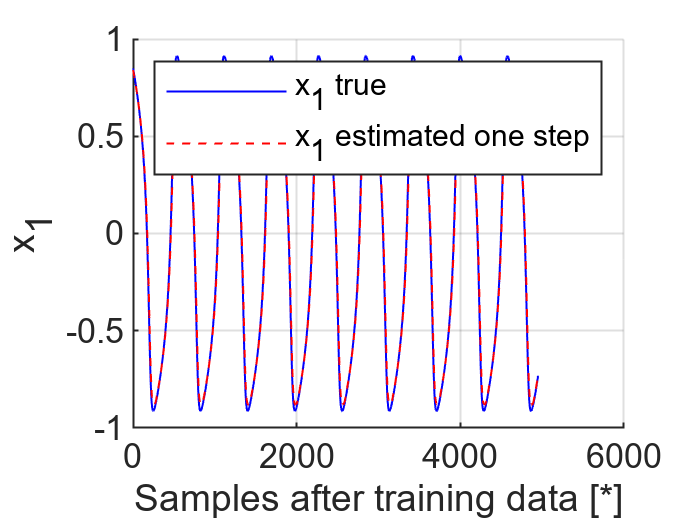

%Making plots of the estimation and the true simulated values for one step
%esitmation

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(x1(5001:10000-d,1),'blue')
plot(PredictionXsave(1,:),'--r')
hold off 
grid
legend('x_1 true','x_1 estimated one step')
xlabel("Samples after training data [*]")
ylabel('x_1')
ax=gca;
exportgraphics(ax,"x1_HAVOK_no_input.pdf")

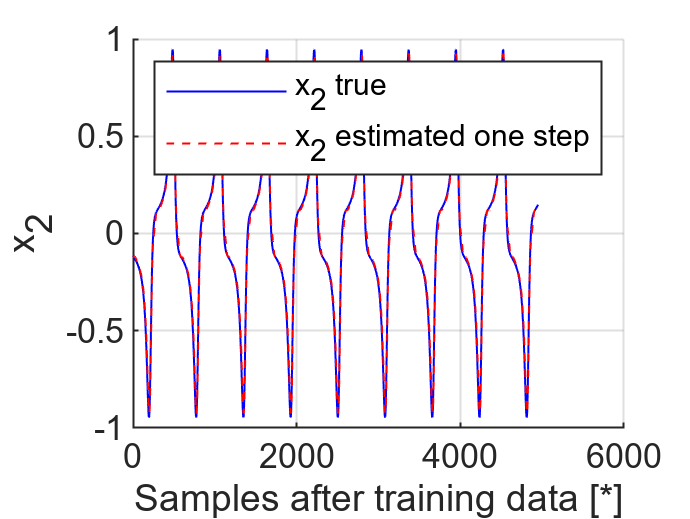



clf
hold on 
plot(x2(5001:10000-d,1),'blue')
plot(PredictionXsave(2,:),'--r')
hold off 
grid
legend('x_2 true','x_2 estimated one step')
xlabel("Samples after training data [*]")
ylabel('x_2')


ax=gca;
exportgraphics(ax,"x2_HAVOK_no_input.pdf")


%Now trying with to preditec only based on the training data 
Hr=xAll(:,5000-(d+1)*ny+1:5000);

for i=1:5000-d

    %Projecting to the V subspace: 
    vk=Pdown*Hr'; 

    %Making prediction:
    vkPred=A*vk; 

    %Transforming the prediction back to the state space representation
    PreditionX=Pup*vkPred;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 

    PredictionXsaveMulti(:,i)=PreditionX'*Cc;
    %Updating xdata
    Hr=[Hr(:,2:end), PreditionX'*Cc];

end 

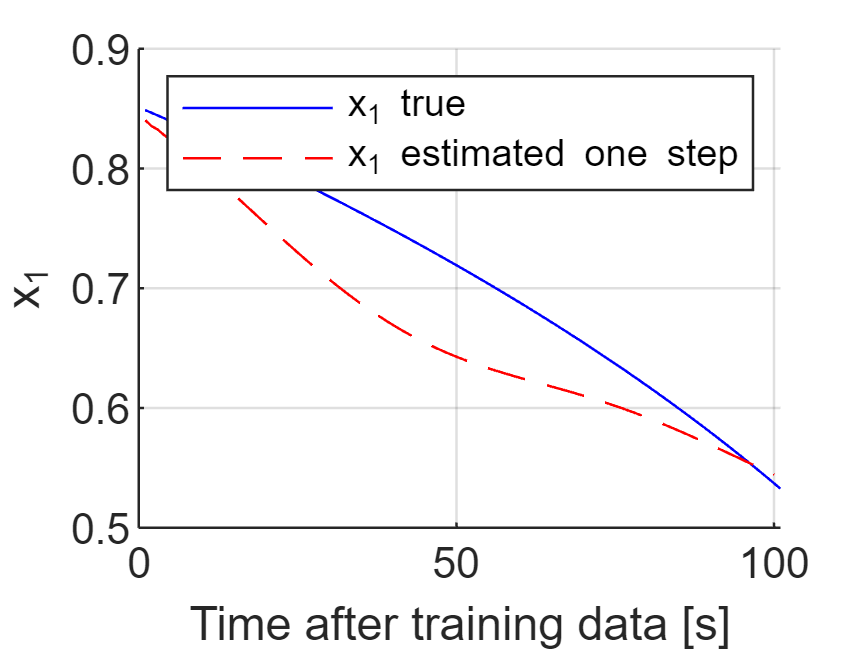

%Comparing the multiple prediction step to the real value of the states
clf
hold on 
plot(x1(5001:5101,1),'blue')
plot(PredictionXsaveMulti(1,1:100),'--r')
hold off 
grid
legend('x_1 true','x_1 estimated one step')
xlabel("Time after training data [s]")
ylabel('x_1')

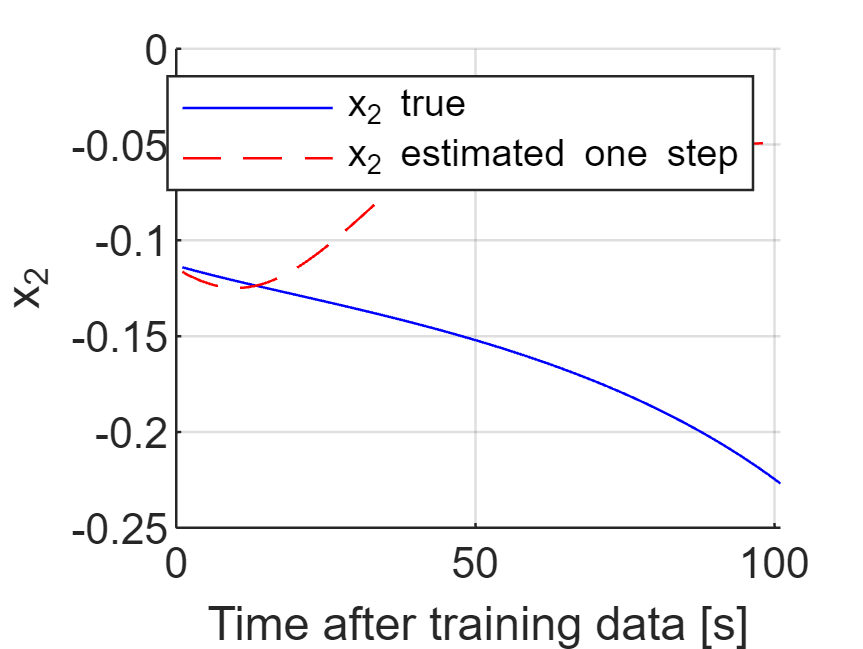

ax=gca;
%exportgraphics(ax,"x1_HAVOK_no_input_multi.pdf")


clf
hold on 
plot(x2(5001:5101,1),'blue')
plot(PredictionXsaveMulti(2,1:100),'--r')
hold off 
grid
legend('x_2 true','x_2 estimated one step')
xlabel("Time after training data [s]")
ylabel('x_2')


ax=gca;
%exportgraphics(ax,"x2_HAVOK_no_input_multi.pdf")

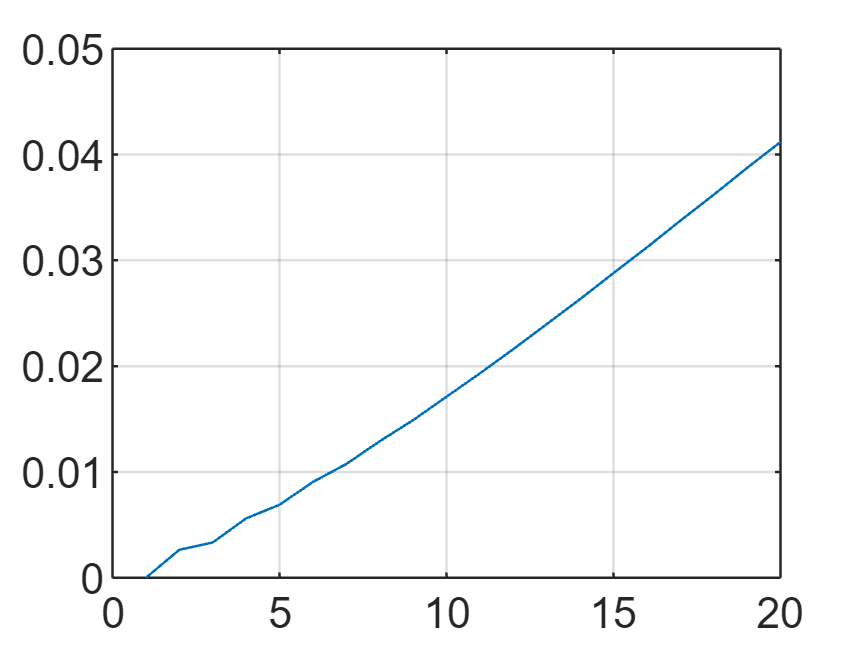

%Plotting error between one step prediction and multi step prediction
Error=abs(PredictionXsave-PredictionXsaveMulti);
clf 
plot(Error(1,1:20))
grid 

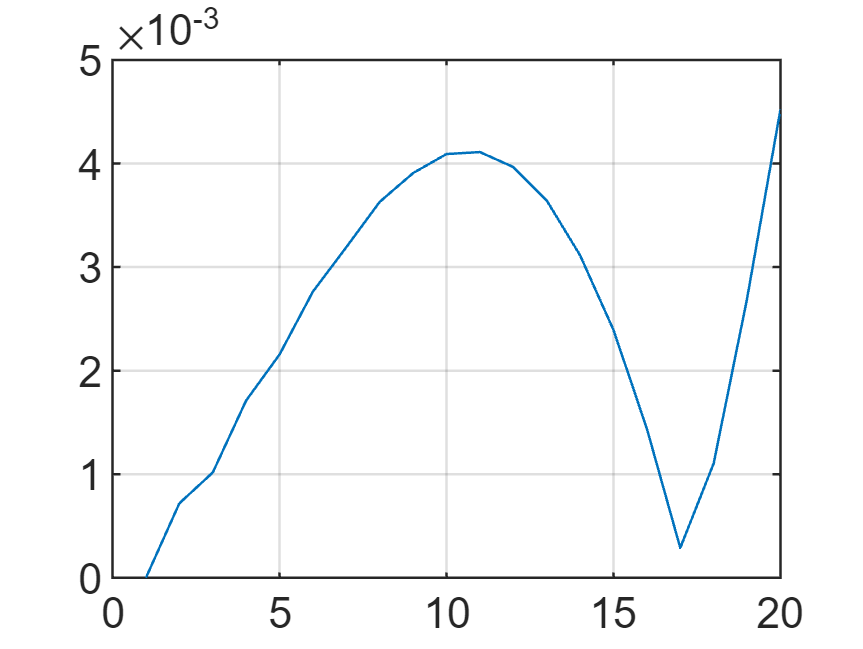

clf 
plot(Error(2,1:20))
grid

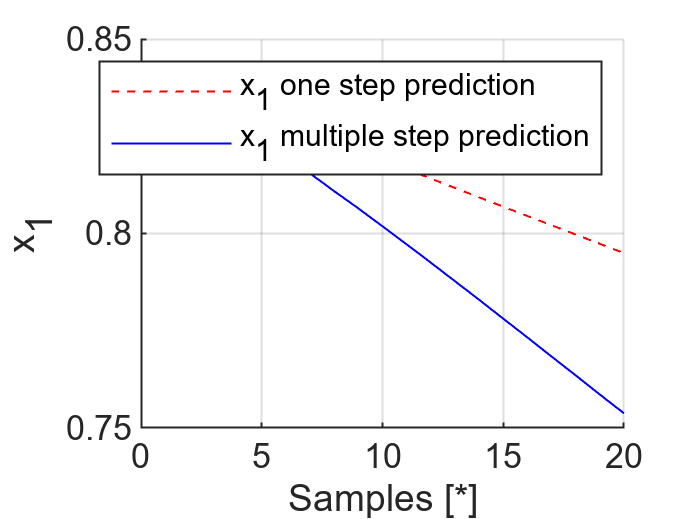

%Comparing one step prediction and multiple step prediction 
clf
hold on 
plot(PredictionXsave(1,1:20),'--r')
plot(PredictionXsaveMulti(1,1:20),'blue')
hold off 
grid
legend('x_1 one step prediction','x_1 multiple step prediction')
xlabel("Samples [*]")
ylabel('x_1')

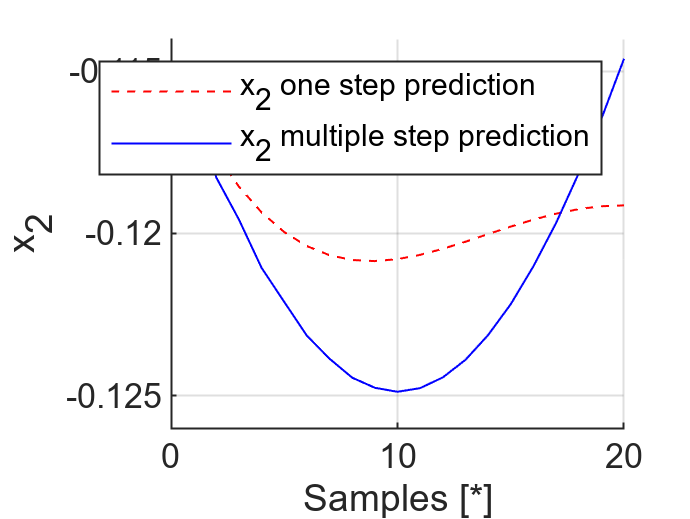

ax=gca;
exportgraphics(ax,"x1_HAVOK_one_vs_multi.pdf")


clf
hold on 
plot(PredictionXsave(2,1:20),'--r')
plot(PredictionXsaveMulti(2,1:20),'blue')
hold off 
grid
legend('x_2 one step prediction','x_2 multiple step prediction')
xlabel("Samples [*]")
ylabel('x_2')

ax=gca;
exportgraphics(ax,"x2_HAVOK_one_vs_multi.pdf")